1.

A=[1,4,2;2,4,100;7,9,7;3,pi,42];
B=log(A);

a=B(2,:)

a =     0.6931    1.3863    4.6052


b=B(2,1)+B(2,2)+B(2,3)

b = 6.6846

c=B(:,2).*A(:,1)

c =     1.3863
    2.7726
   15.3806
    3.4342


d=max(c)

d = 15.3806

e=(A(1,1)./B(1,3))+(A(1,2)./B(2,3))+(A(1,3)./B(3,3))

e = 3.3391

2.

v_0=50;
A=50;
g=9.81;

radian_A=deg2rad(A);

t_hit=2*v_0*sin(radian_A)/g;
y_max=(v_0*sin(radian_A))^2/(2*g);

t=linspace(0,t_hit,100);

x=(v_0*cos(radian_A))*t;
y=(v_0*sin(radian_A))*t-(g*t.^2)/2;

a_1=t_hit

a_1 = 7.8088

a_2=y_max

a_2 = 74.7737

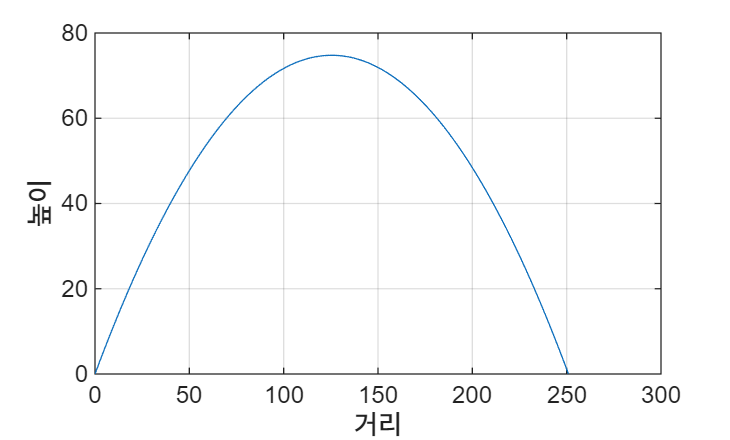



b_1=plot(x,y);
xlabel('거리');
ylabel('높이');
grid on;

3.

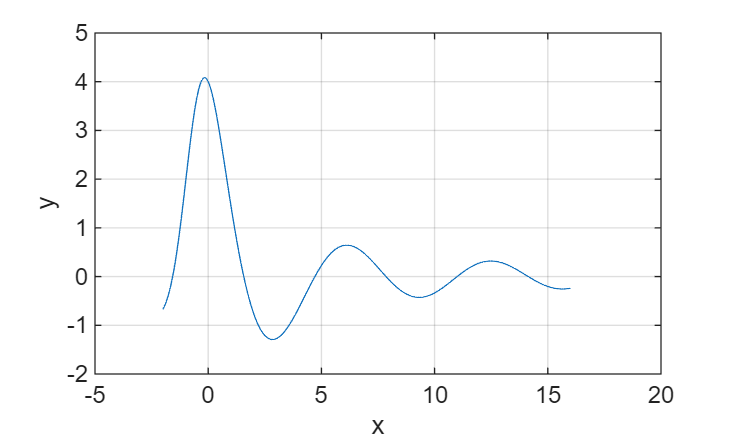

x=linspace(-2,16,1000);
y=4*cos(x)./(x+exp(-0.75*x));
plot(x,y);
xlabel('x');
ylabel('y');
grid on;

4.

price=[300;550;400;250;500];
count=[5,4,6;3,2,4;6,5,3;3,5,4;2,4,3];

a1=price.*count

a1 =         1500        1200        1800
        1650        1100        2200
        2400        2000        1200
         750        1250        1000
        1000        2000        1500



b1=sum(a1)

b1 =         7300        7550        7700



c1=sum(a1,2)

c1 =         4500
        4950
        5600
        3000
        4500



d1=sum(a1,"all")

d1 = 22550

5.

a_3=conv([5,0,-3,7,10],[4,-7,9,2])

a_3 =     20   -35    33    59   -36   -13   104    20



[b_3,b_4]=deconv([5,-7,2,8],[6,3,-2])

b_3 =     0.8333   -1.5833


b_4 =          0         0    8.4167    4.8333



x=5;
c_3=(36*x^3-8*x^2+2)/(36*x^3-5*x^2+4*x-3)

c_3 = 0.9795

7.

bridges(1)= struct('Location','SmithSt.','MaxLoad',80,'YearBuilt',1928,'Lifetime',2025);
bridges(2)= struct('Location','HopeAve.','MaxLoad',90,'YearBuilt',1950,'Lifetime',2027);
bridges(3) = struct('Location','ClarkSt.','MaxLoad',85,'YearBuilt',1933,'Lifetime',2024);
bridges(4) = struct('Location','NorthRd.','MaxLoad',100,'YearBuilt',1960,'Lifetime',2023)

bridges = 다음 필드를 포함한 1×4 struct 배열:
    Location
    MaxLoad
    YearBuilt
    Lifetime



bridges(3).Lifetime = 2026;
bridges(3)

ans = 다음 필드를 포함한 struct:
     Location: 'ClarkSt.'
      MaxLoad: 85
    YearBuilt: 1933
     Lifetime: 2026



bridges(5) = struct('Location','ShoreRd.','MaxLoad',85,'YearBuilt',1997,'Lifetime',2022);
